# **Task_04:**   Use a **DC Motor** and **Rack and Pinion** **Gear** mechanism to excite the 3-dof system

In this example we'll highlight the multidomain capability of **Simscape** by exciting the 3-dof Spring Mass Damper (SMD) System with a **Rack and Pinion gear** setup being driven by a **DC Motor**. 

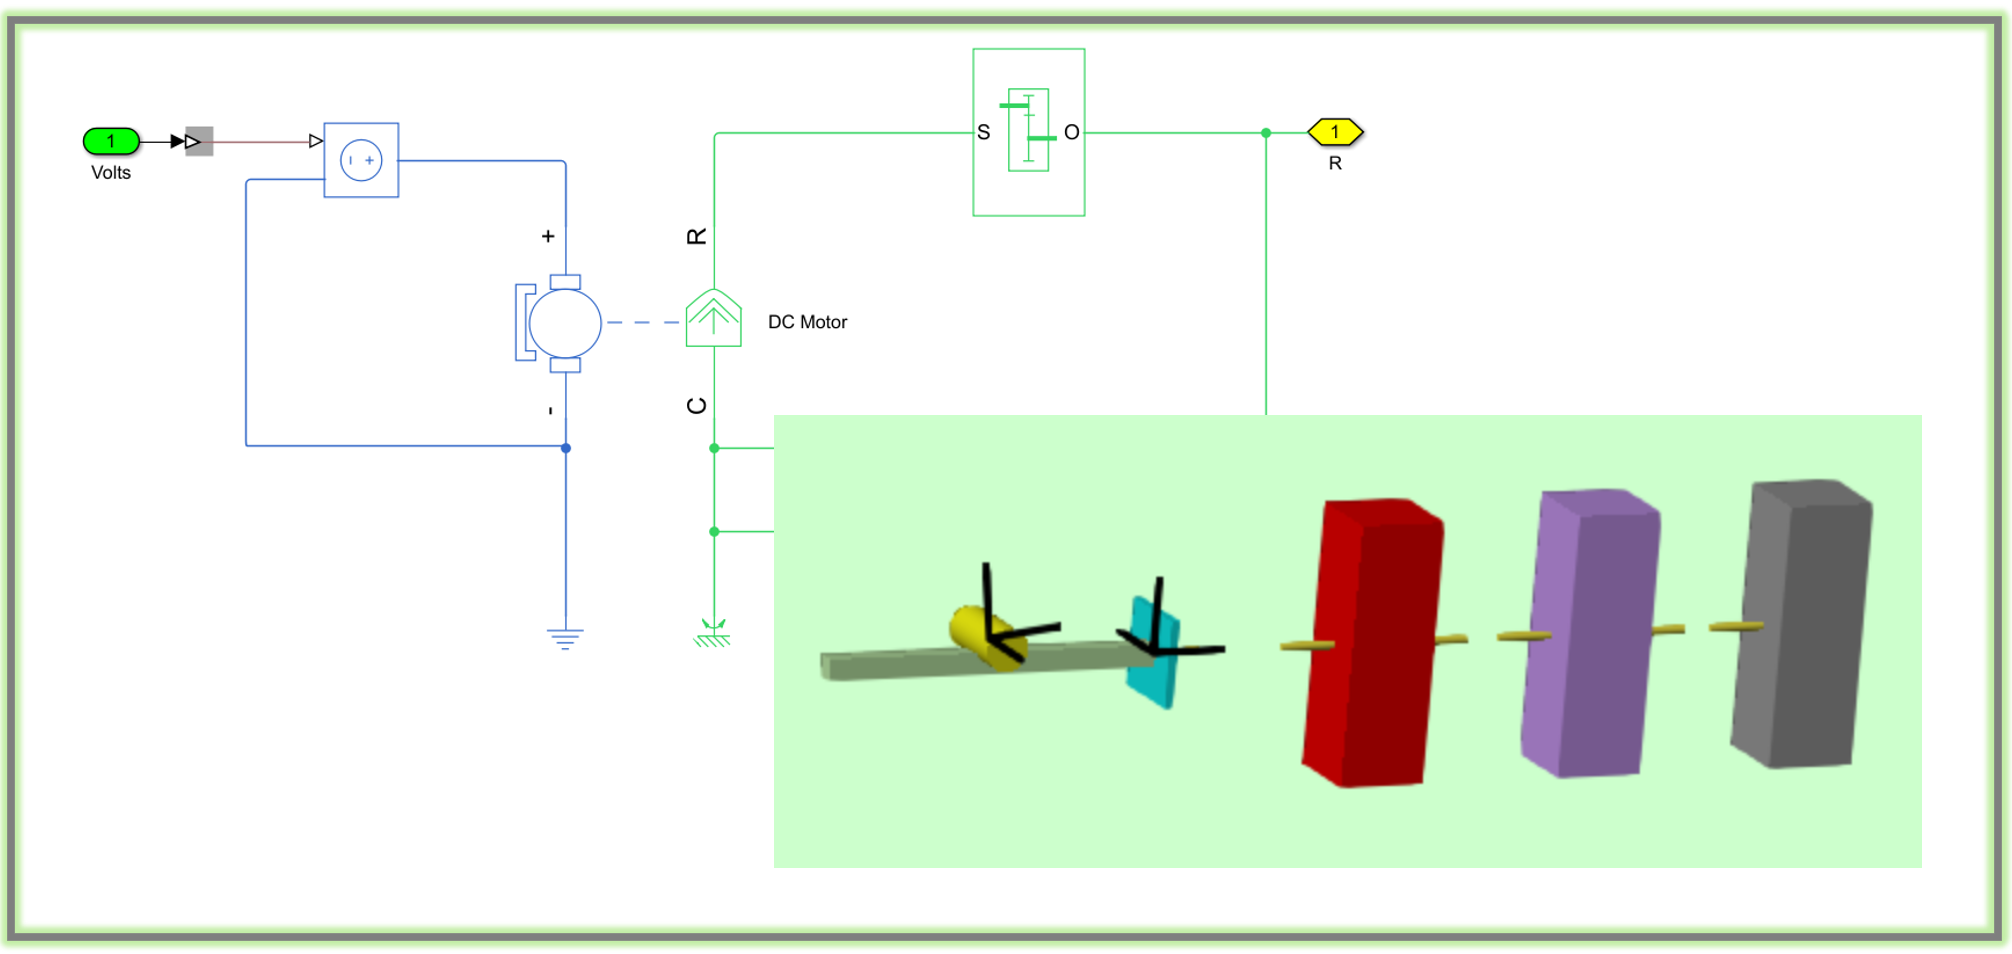

Recall the 3-dof SMD system:

- We have 3 masses - $m_1 \;,m_2 \;\;,m_3$

- The degrees of freedom are - $z_1 \;,z_2 \;\;,z_3$ 

- Each dof is measured from an INERTIAL frame coinciding with the UNstretched spring positions

- We have a "ground patch" that can move -  $z_G$  

- We have 3 springs, and although they have not been drawn each spring has a damper in parallel.

- The UN stretched lengths of each spring are - $L_G \;\;,L_1 \;\;,L_2$

- Each mass is acted upon by an external force - $F_1 \;\;,F_2 \;\;,F_3$

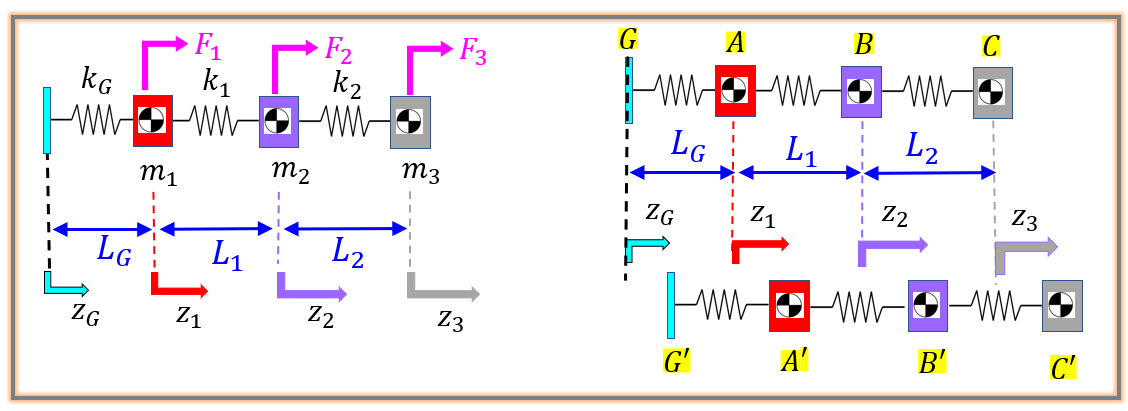

## Newton derivation of the Mechanical Equations of motion

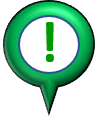The Newton 2nd Law derivation is summarized in the function file:

- [`bh_newton_smd_3dof_model_MCK.mlx`](matlab: edit bh_newton_smd_3dof_model_MCK.mlx)

## Clear your workspace

clear

## Model parameters

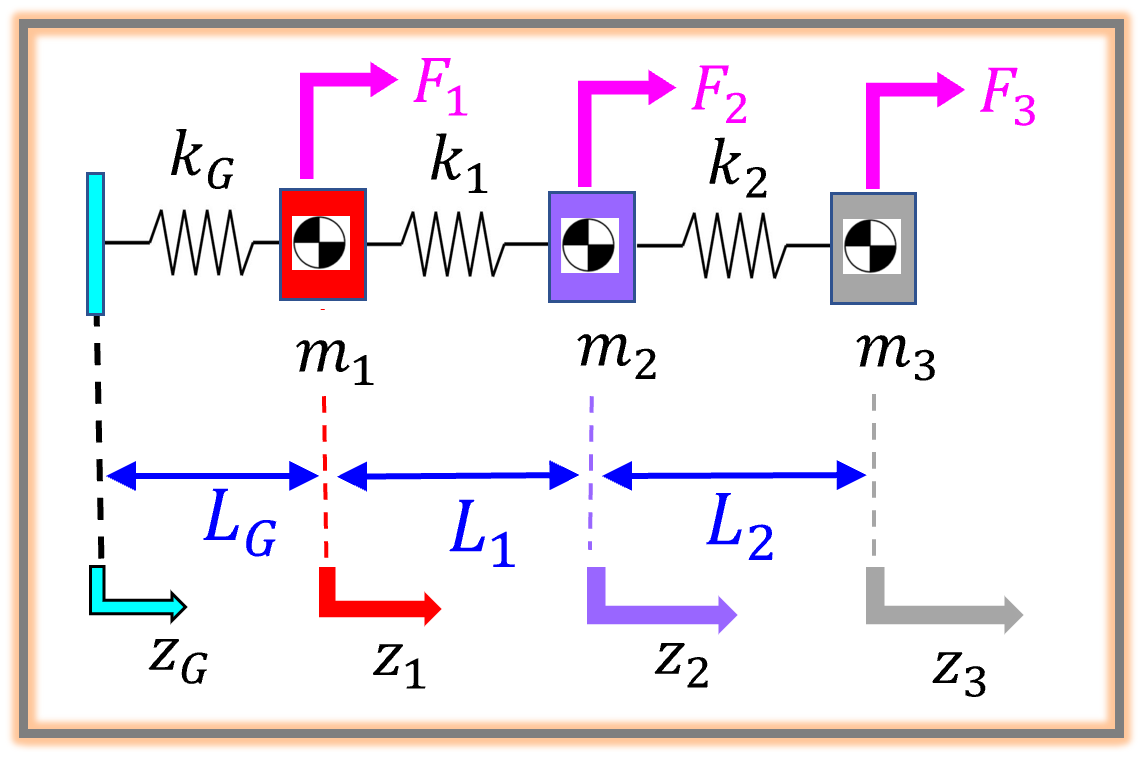

Consult database for parameters :

- See: [` bh_smd_3dof_tmd_params_CLS.m `](matlab:  open  bh_smd_3dof_tmd_params_CLS.m)

- See:   [`bh_smd_3dof_tmd_params_database.xlsx`](matlab:  winopen bh_smd_3dof_tmd_params_database.xlsx)

param_DB = bh_smd_3dof_tmd_params_CLS("bh_smd_3dof_tmd_params_database.xlsx", "CONFIG_FLEX");

Masses:

params_T.m1 = param_DB.m1;  % (kg)
params_T.m2 = param_DB.m2;  % (kg)
params_T.m3 = param_DB.m3;  % (kg)

Spring Stiffness:

params_T.k1 = param_DB.k1;   % (N/m)
params_T.k2 = param_DB.k2;   % (N/m)
params_T.kG = param_DB.kG;   % (N/m)

Spring Damping:

BETA_CONST_PROP_DAMPING = 1e-3;
params_T.c1 = BETA_CONST_PROP_DAMPING*params_T.k1;    % (N/(m/s))
params_T.c2 = BETA_CONST_PROP_DAMPING*params_T.k2;    % (N/(m/s))
params_T.cG = BETA_CONST_PROP_DAMPING*params_T.kG;    % (N/(m/s))

Spring UNstretched Length:

params_T.L1 = param_DB.L1; % (m)
params_T.L2 = param_DB.L2; % (m)
params_T.LG = param_DB.LG;  % (m)

So echo our model parameters

params_T

params_T = struct with fields:
    m1: 0.5080
    m2: 0.5080
    m3: 0.5080
    k1: 124
    k2: 124
    kG: 124
    c1: 0.1240
    c2: 0.1240
    cG: 0.1240
    L1: 0.2500
    L2: 0.2500
    LG: 0.2500


## Initial Conditions(NEWTON)

Mass ICs

IC_Newt_T.z_col    = [0,0,0]' ;  % z1,z2,z3
IC_Newt_T.zdot_col = [0,0,0]' ;

Ground patch ICs

IC_Newt_T.zG       = 0;
IC_Newt_T.zG_dot   = 0;

## Initial Conditions(Simscape Multibody PRISMATIC joint)

In our Simscape Multibody model, we'll use [`PRISMATIC joints`](https://www.mathworks.com/help/releases/R2025b/sm/ref/prismaticjoint.html) to represent our springs

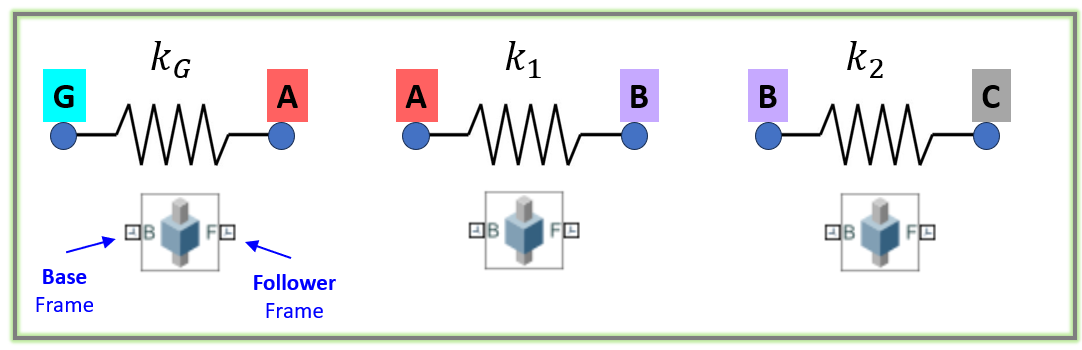

Each spring (our Prismatic joints) needs to be configured with 

- The **position** of the FOLLOWER frame relative to the BASE 

- The **velocity** of the FOLLOWER frame relative to the BASE

Which we can interpret as: 

- **POSITION**:    $\Longrightarrow$     Initial spring length and an 

- **VELOCITY**:    $\Longrightarrow$     Initial spring length rate of change (say velocity) 

To compute this, we'll utilize our **Newton Initial Conditions** and the **UNstretched spring lengths**

- 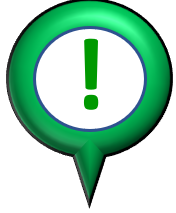 NOTE:  Simscape Multibody allows for 3D mechanical systems to be modelled ... so we need to incorporate relevant geometry parameters to cater for this. 

So, consider the following schematic:

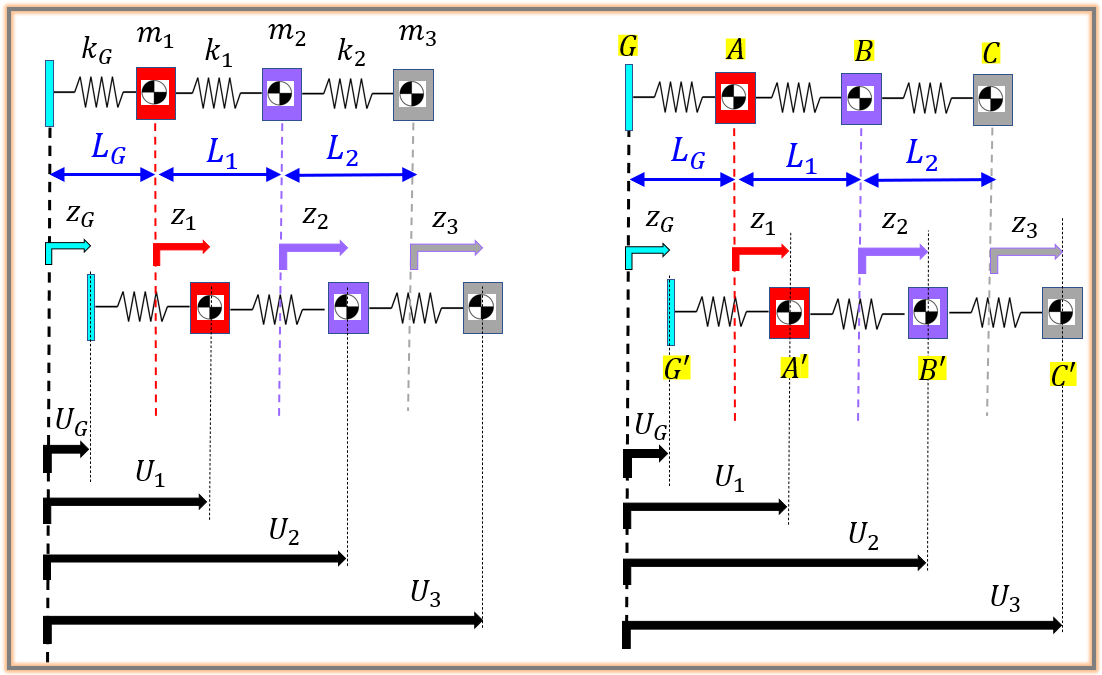

From the above figure we can write:

- 
$$U_G =z_G$$


- 
$$U_1 \;=L_G \;+z_1$$


- 
$$U_2 =L_G +L_1 +z_2$$


- 
$$U_3 =L_G \;+L_1 \;+L_2 \;+z_3$$


So the Initial Spring Lengths are:

- 
$$L_{G^{\prime } A^{\prime } } \;=\;U_1 -U_G \;=\;\left(L_G \;+z_1 \right)-\left(z_G \right)\;=\;\;L_G \;+\left(z_1 -z_G \right)$$


- 
$$L_{A^{\prime } B^{\prime } } \;=U_2 \;-U_1 \;\;=\;\left(L_G +L_1 +z_2 \right)-\left(L_G \;+z_1 \right)\;=L_1 \;+\;\left(z_2 -z_1 \right)$$


- 
$$L_{B^{\prime } C^{\prime } } \;=U_3 \;-U_2 \;\;=\;\left(L_G +L_1 +L_2 +z_3 \right)-\left(L_G \;+L_1 +z_2 \right)\;=L_2 \;+\;\left(z_3 -z_2 \right)$$


And similarly the Initial Spring Length rates of change are:

- 
$$\frac{\mathrm{d}}{\mathrm{d}t}\left(L_{G^{\prime } A^{\prime } } \right)\;=\;\;\left({\dot{z} }_1 -{\dot{z} }_G \right)$$


- 
$$\frac{\mathrm{d}}{\mathrm{d}t}\left(L_{A^{\prime } B^{\prime } } \right)\;=\;\;\left({\dot{z} }_2 -{\dot{z} }_1 \right)$$


- 
$$\frac{\mathrm{d}}{\mathrm{d}t}\left(L_{B^{\prime } C^{\prime } } \right)\;=\;\;\left({\dot{z} }_3 -{\dot{z} }_2 \right)$$


IC_PrisJ_T.springG.pos = (IC_Newt_T.z_col(1)    - IC_Newt_T.zG) + params_T.LG;
IC_PrisJ_T.springG.vel = (IC_Newt_T.zdot_col(1) - IC_Newt_T.zG_dot);

IC_PrisJ_T.spring1.pos = (IC_Newt_T.z_col(2)    - IC_Newt_T.z_col(1)) + params_T.L1;
IC_PrisJ_T.spring1.vel = (IC_Newt_T.zdot_col(2) - IC_Newt_T.zdot_col(1));

IC_PrisJ_T.spring2.pos = (IC_Newt_T.z_col(3)    - IC_Newt_T.z_col(2)) + params_T.L2;
IC_PrisJ_T.spring2.vel = (IC_Newt_T.zdot_col(3) - IC_Newt_T.zdot_col(2));

## Some Simscape visualization artifacts

I'll insert some light weight cylinders to denote the springs - this is for visualization purposes only and will have almost no effect on the system dynamics (e.g.:   mass = ${10}^{-10} \;$kg)

vis_itemT.r = 0.05 * 0.1;          %(m)
vis_itemT.L = params_T.L1/4; %(m)
params_T.m  = 1e-10;          % (kg)

## Modal Analysis

Extract the UNdamped natural frequencies from the SMD system.  See:

- [`bh_newton_smd_3dof_model_MCK.mlx`](matlab: edit bh_newton_smd_3dof_model_MCK.mlx)

- [`bh_newton_smd_3dof_eig.mlx`](matlab:  edit bh_newton_smd_3dof_eig.mlx)

 [M_mat, ~, K_mat, ~] = bh_newton_smd_3dof_model_MCK( params_T.m1, params_T.m2, params_T.m3, ...
                                                      params_T.kG, params_T.k1, params_T.k2, ...
                                                     "DAMPING_C", [params_T.cG, params_T.c1, params_T.c2] );

[w2_list, eVec_PHI] = bh_newton_smd_3dof_eig( params_T.m1, params_T.m2, params_T.m3, ...
                                              params_T.kG, params_T.k1, params_T.k2 );

Great, so let's summarise what we have. 

- Our UNdamped Natural frequencies of vibration are:   $\omega \;\;\;\left\lbrack \frac{\mathrm{rad}}{\sec }\right\rbrack$:

w_list = sqrt( w2_list(:) );
w_table = array2table( [w2_list(:), w_list, w_list/(2*pi)], "VariableNames", {'w^2', 'w_radpersec', 'f_Hz'}  )

w_table = 3×3 table
     w^2      w_radpersec     f_Hz 
    ______    ___________    ______

    48.346      6.9531       1.1066
    379.56      19.482       3.1007
    792.57      28.153       4.4806

	Get insights using Copilot


Confirm we have normalized eigenvectors 

-   
$$I\;\;={\;\;V}^T \ldotp M\ldotp V$$


- 
$$\;\Omega^{2\;} =\;\;V^T \ldotp K\ldotp V$$


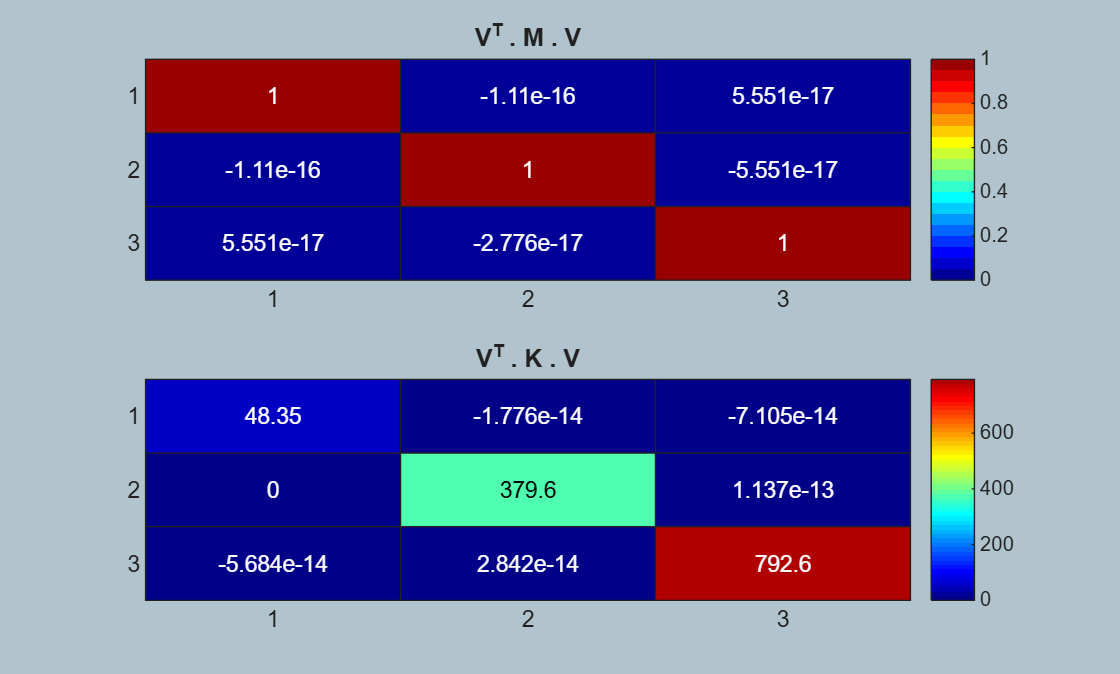

Im_mat      = eVec_PHI.' * M_mat * eVec_PHI;
w2_mat      = eVec_PHI.' * K_mat * eVec_PHI;

figure;
    subplot(2,1,1);   heatmap(Im_mat, "Colormap", jet(20) );  title("V^T . M . V")
    subplot(2,1,2);   heatmap(w2_mat, "Colormap", jet(50) );  title("V^T . K . V")

## Open the Simulink and Simscape Multibody model

  w_baseline = w_list;  

Now open and run the Simulink model that contains our multidomain system

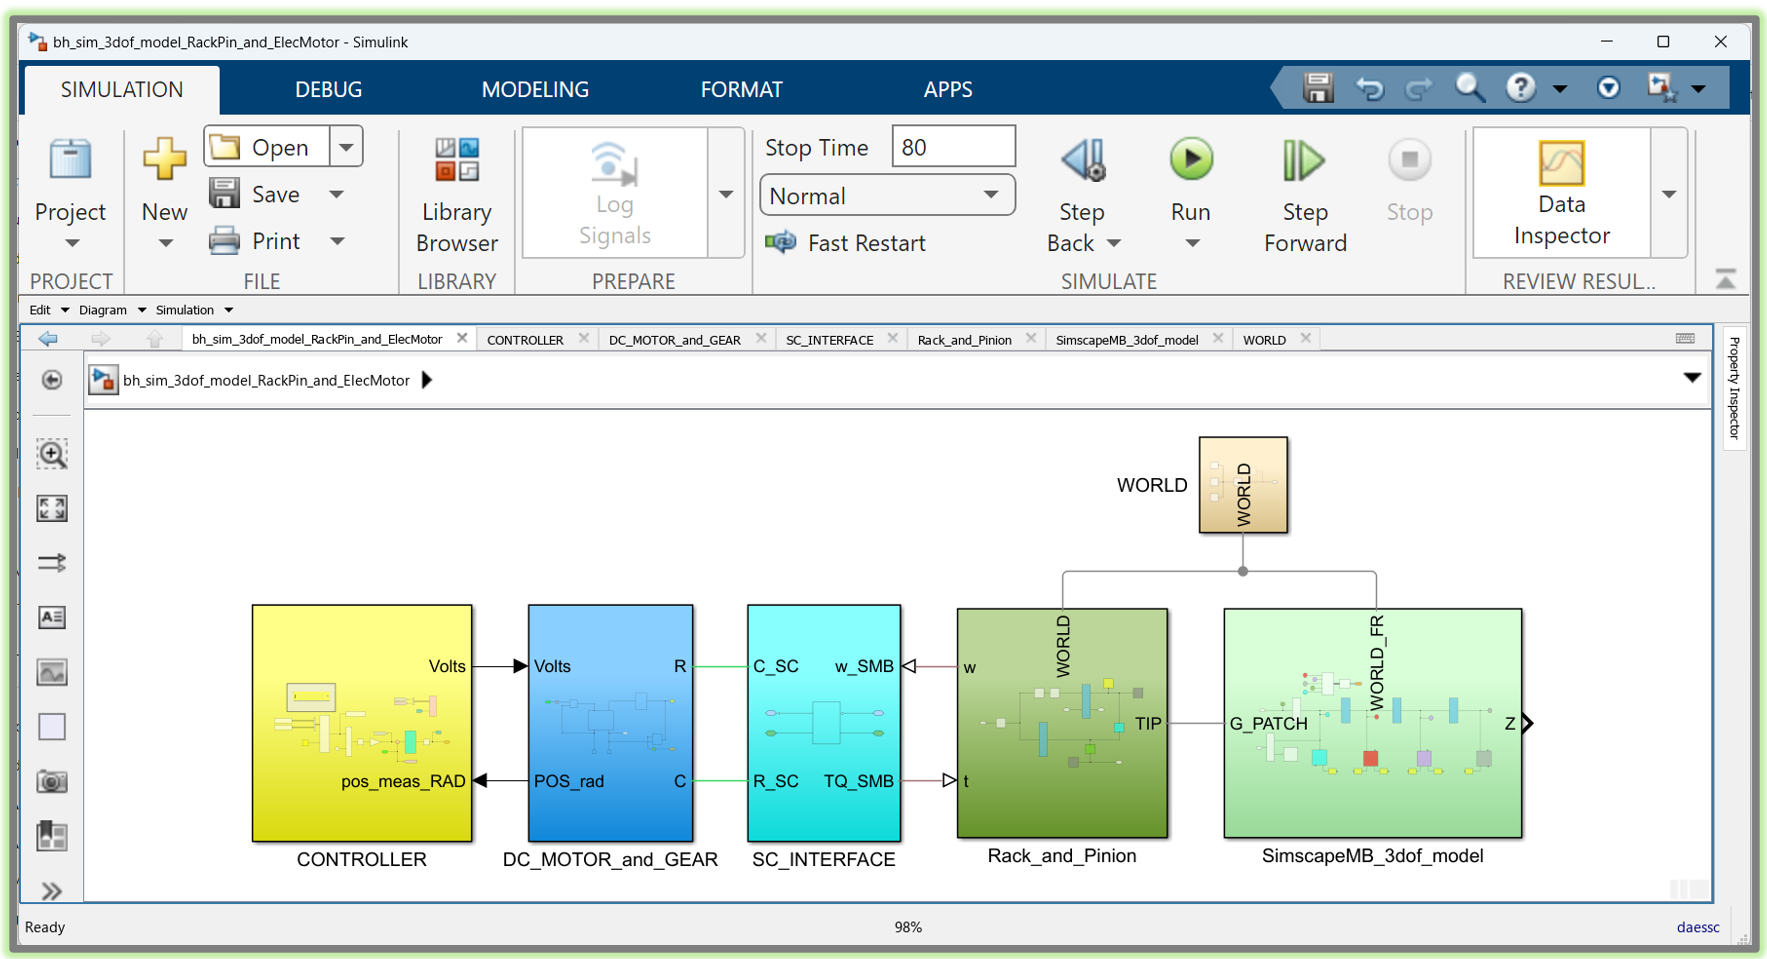

open_system("bh_sim_3dof_model_RackPin_and_ElecMotor.slx")